# Specify Regression Model with SARIMA Errors

This example shows how to specify a regression model with multiplicative seasonal ARIMA errors.

Load the Airline data set from the MATLAB® root folder, and load the recession data set. Plot the monthly passenger totals and log-totals.

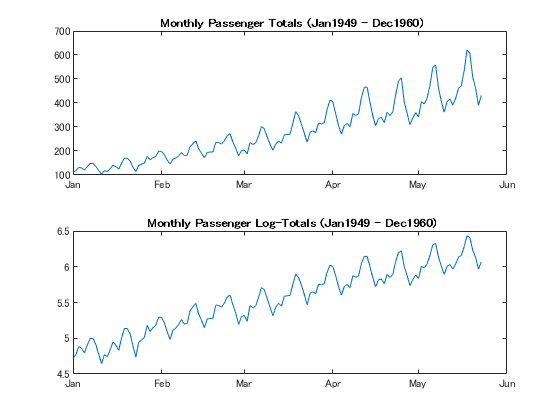

load(fullfile(matlabroot,'examples','econ','Data_Airline.mat'))
load Data_Recessions; 

y = Data; 
logY = log(y); 

figure
subplot(2,1,1) 
plot(y)
title('{\bf Monthly Passenger Totals (Jan1949 - Dec1960)}')
datetick
subplot(2,1,2)
plot(log(y))
title('{\bf Monthly Passenger Log-Totals (Jan1949 - Dec1960)}')
datetick

The log transformation seems to linearize the time series. 

Construct this predictor, which is whether the country was in a recession during the sampled period. `0` means the country was not in a recession, and `1` means that it was in a recession. 

X = zeros(numel(dates),1); % Preallocation
for j = 1:size(Recessions,1)
    X(dates >= Recessions(j,1) & dates <= Recessions(j,2)) = 1;
end

Fit the simple linear regression model,


$${y_t} = c + {X_t}\beta  + {u_t}$$


to the data. 

Fit = fitlm(X,logY);

`Fit` is a `LinearModel` that contains the least squares estimates. 

Perform a residual diagnosis by plotting the residuals several ways. 

figure
subplot(2,2,1)
plotResiduals(Fit,'caseorder','ResidualType','Standardized',...
    'LineStyle','-','MarkerSize',0.5)
h = gca;
h.FontSize = 8; 
subplot(2,2,2)
plotResiduals(Fit,'lagged','ResidualType','Standardized')
h = gca;
h.FontSize = 8;
subplot(2,2,3)
plotResiduals(Fit,'probability','ResidualType','Standardized')
h = gca;
h.YTick = h.YTick(1:2:end); 
h.YTickLabel = h.YTickLabel(1:2:end,:); 
h.FontSize = 8;
subplot(2,2,4)
plotResiduals(Fit,'histogram','ResidualType','Standardized')
h = gca;
h.FontSize = 8; 

r = Fit.Residuals.Standardized;
figure
subplot(2,1,1)
autocorr(r)
h = gca;
h.FontSize = 9;
subplot(2,1,2)
parcorr(r)    
h = gca;
h.FontSize = 9;

The residual plots indicate that the residuals are autocorrelated. The probability plot and histogram seem to indicate that the residuals are Gaussian. 

The ACF of the residuals confirms that they are autocorrelated. 

Take the 1st difference of the residuals and plot the ACF and PACF of the differenced residuals. 

dR = diff(r);

figure
subplot(2,1,1)
autocorr(dR,'NumLags',50)
h = gca;
h.FontSize = 9;
subplot(2,1,2)
parcorr(dR,'NumLags',50)    
h = gca;
h.FontSize = 9;

The ACF shows that there are significantly large autocorrelations, particularly at every 12th lag. This indicates that the residuals have 12th degree seasonal integration. 

Take the first and 12th differences of the residuals. Plot the differenced residuals, and their ACF and PACF. 

DiffPoly = LagOp([1 -1]);
SDiffPoly = LagOp([1 -1],'Lags',[0, 12]);
diffR = filter(DiffPoly*SDiffPoly,r);

figure
subplot(2,1,1)
plot(diffR)
axis tight
subplot(2,2,3)
autocorr(diffR)
axis tight
h = gca;
h.FontSize = 7;
subplot(2,2,4)
parcorr(diffR)
axis tight    
h = gca;
h.FontSize = 7; 

The residuals resemble white noise (with possible heteroscedasticity). According to Box and Jenkins (1994), Chapter 9, the ACF and PACF indicate that the unconditional disturbances are an $\rm{IMA}(0,1,1)\times(0,1,1)_{12}$ model. 

Specify the regression model with $\rm{IMA}(0,1,1)\times(0,1,1)_{12}$ errors: 


$$\begin{array}{c}{y_t} = {X_t}\beta  + {u_t}\\\left( {1 - L} \right)\left( {1 - {L^{12}}} \right){u_t} = \left( {1 + {b_1}L} \right)\left( {1 + {B_{12}}{L^{12}}} \right){\varepsilon _t}.\end{array}$$


Mdl = regARIMA('MALags',1,'D',1,'Seasonality',12,'SMALags',12) 

`Mdl` is a regression model with $\rm{IMA}(0,1,1)\times(0,1,1)_{12}$ errors. By default, the innovations are Gaussian, and all parameters are `NaN`. The property:

- `P` = *p* + *D* + $sp_s$ + *s* = 0 + 1 + 0 + 12 = 13. 

- `Q` = *q* + $sq_s$ = 1 + 12 = 13. 

Therefore, the software requires at least 13 presample observations to initialize the model. 

Pass `Mdl`, `y`, and `X` into `estimate` to estimate the model. In order to simulate or forecast responses using `simulate` or `forecast`, you need to set values to all parameters.

References:

Box, G. E. P., G. M. Jenkins, and G. C. Reinsel. *Time Series Analysis: Forecasting and Control*. 3rd ed. Englewood Cliffs, NJ: Prentice Hall, 1994. 